# Analyzing tumor vascularity with Quantitative Tumor-Associated Vasculature (QuanTAV) 

## Introduction

This interactive live script is a companion to the manuscript "Computational Measurements of Tumor-Associated Vasculature Morphology on Clinical Imaging as a Predictive and Prognostic Biomarker of Treatment Response in Multiple Cancers," currently under review. 

In this tutorial, we will be demonstrating how to set up the package and use it for the analysis of tumor vessels. We will install the necessary packages, generate synthetic vessel volumes with varying degrees of vascular architectural disorder, and skeletonize the branches of the vessel network via a fast-marching approach. Finally, we extract QuanTAV Organization and Morphology features and observe how they differ based on vessel architecture. 

## Setup

First we set up our paths, as well as compile packages obtained and modified from the Mathworks FileExchange. Packages that have been modified for our approach are included in the from_mathworks/ directory. The ones that we used as is will need to be downloaded and added by the user.  The list of external packages used and incorporated in this codebase is the following: 

- [Accurate FastMarching](https://www.mathworks.com/matlabcentral/fileexchange/24531-accurate-fast-marching) - Dirk-Jan Kroon (included)

- [circlefit3d - fit circle to three points in 3d space](https://www.mathworks.com/matlabcentral/fileexchange/34792-circlefit3d-fit-circle-to-three-points-in-3d-space) - Johannes Korsawe (included)

- [Beautiful and distinguishable line colors + colormap](https://www.mathworks.com/matlabcentral/fileexchange/42673-beautiful-and-distinguishable-line-colors-colormap) - Jonathan C. Lansey (needs added)

- [Perceptually uniform colormaps](https://www.mathworks.com/matlabcentral/fileexchange/51986-perceptually-uniform-colormaps) - Ander Biguri (needs added)

root_dir = pwd;
addpath('data\');
addpath('vessel_features\');
addpath('visualization\');
addpath('from_mathworks\');
addpath('from_mathworks\FastMarching_version3b\functions\');
addpath('from_mathworks\FastMarching_version3b\images\');
addpath('from_mathworks\FastMarching_version3b\shortestpath\');

cd('from_mathworks\FastMarching_version3b\');
compile_c_files;

Building with 'Microsoft Visual C++ 2015 (C)'.
MEX completed successfully.
Building with 'Microsoft Visual C++ 2015 (C)'.
MEX completed successfully.
Building with 'Microsoft Visual C++ 2015 (C)'.
MEX completed successfully.
compiled!


cd(root_dir);

## Generating synthetic vessel data

We are going to create some vessel data to allow us to explore the relationship between the construction of the vessel network and QuanTAV features. Default values are specified below, but feel free to toy with these further. The function create_synthetic_vessel_data creates a spherical tumor centered in the volume, then draw a series of vessels originating from the tumor (n_tumor_vessels) or outside of it (n_other_vessels). Vessel lines are drawn between two randomly selected points by adding [Perlin noise](https://en.wikipedia.org/wiki/Perlin_noise) one dimension at a time. The function that does this, make_random_1D_line, is modified from code provided with this [post](https://www.mathworks.com/matlabcentral/answers/512092-create-random-paths-between-two-known-points-in-3d#answer_421241) by user Image Analysis on the MATLAB Central forum.

n_tumor_vessels = 15; 
n_other_vessels = 5; 
numpoints=5;
sz = [101,101,101];
tumor_radius = 10; 
main_vessel_draw_radius = 75;
max_num_branches = 3;
branch_probability = .65;
branching_radius = 15;
vessel_width = [1,2];

In addition to the above parameters, create_synthetic_vessel_data also has a smoothness setting that influences the magnitude of perturbations made to a line between two points across a fixed number of iterations. Higher smoothness yields less extreme alterations to a line and thus results in a more organized vessel network. We are going to set our smoothness relatively high for now, to a value of 3. Let's generate a tumor (seg_t) and vessel (seg_v) segmentation and visualize them. 

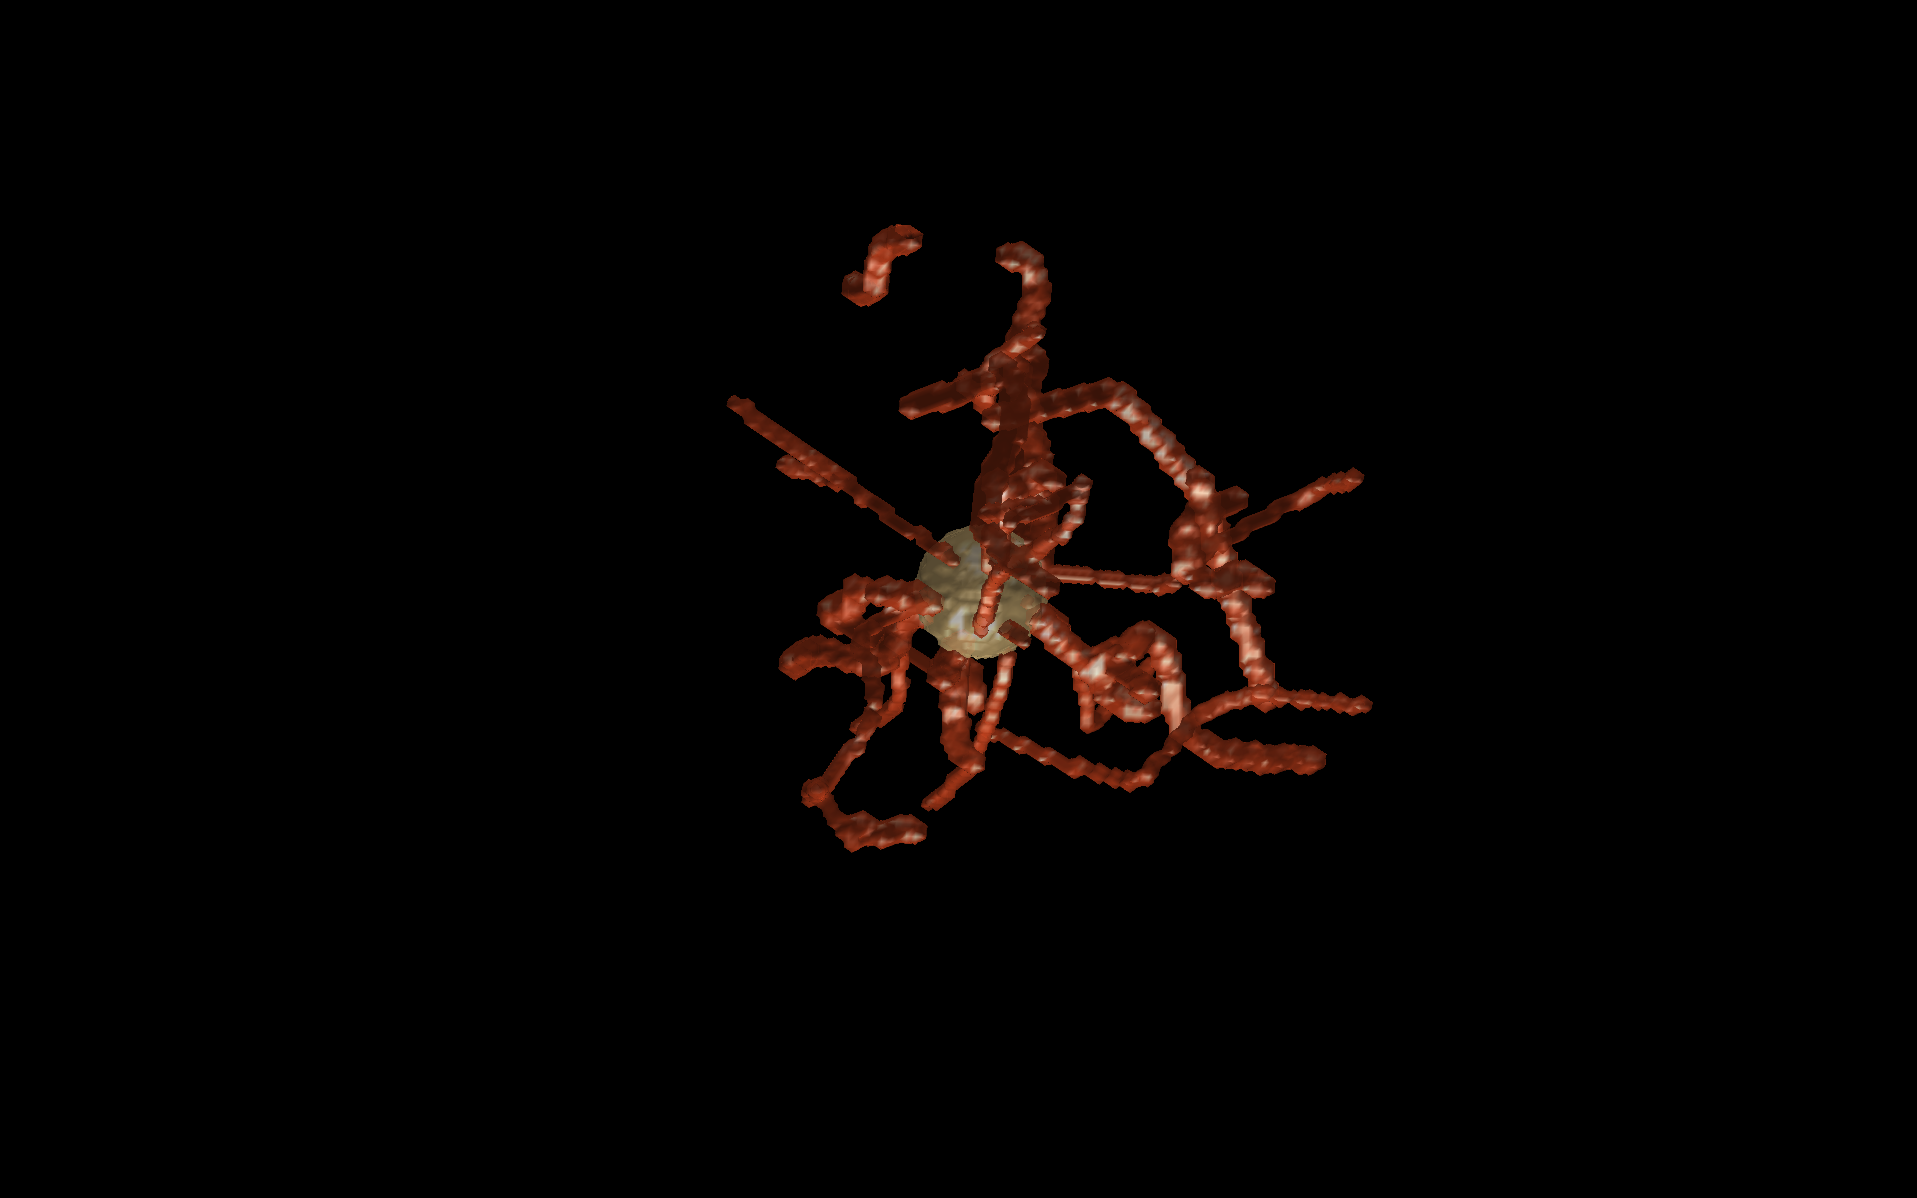

rng(2021)
smoothness = 3;
[seg_t,seg_v] = create_synthetic_vessel_data(n_tumor_vessels, n_other_vessels, smoothness, numpoints, ... 
        sz, tumor_radius, main_vessel_draw_radius,max_num_branches,...
        branch_probability,branching_radius, vessel_width);
visualize_tumor_and_vessels(seg_v,seg_t)

## Identifying branches and skeletonization

Prior to analysis, we must divide the vessel network into branches and identify the centerines of each. We used a fast-marching algorithm slightly modified from the one provided by Dirk-Jan Kroon [here](https://www.mathworks.com/matlabcentral/fileexchange/24531-accurate-fast-marching) on the Mathworks File Exchange. Note, this may take a few minutes.

S = skeleton(seg_v|seg_t);

Distance Map Constructed
Find Branches Iterations : 0
Find Branches Iterations : 1
The shortest path trace did not finish at the source point
Find Branches Iterations : 2
Find Branches Iterations : 3
Find Branches Iterations : 4
Find Branches Iterations : 5
Find Branches Iterations : 6
Find Branches Iterations : 7
Find Branches Iterations : 8
Find Branches Iterations : 9
Find Branches Iterations : 10
Find Branches Iterations : 11
Find Branches Iterations : 12
The shortest path trace did not finish at the source point
Find Branches Iterations : 13
The shortest path trace did not finish at the source point
Find Branches Iterations : 14
The shortest path trace did not finish at the source point
Find Branches Iterations : 15
Find Branches Iterations : 16
Find Branches Iterations : 17
The shortest path trace did not finish at the source point
Find Branches Iterations : 18
Skeleton Branches Found : 39


branch_lengths = [];
for ii = 1:length(S)
    branch_lengths(ii) = size(S{ii},1);
end
fprintf('Skeleton contains %d branches, with an average of %0.2f points each',length(S),mean(branch_lengths))

Skeleton contains 39 branches, with an average of 55.95 points each

## Computing QuanTAV features 

Now that we have generated tumor and vessel segmentartions, and computed their corresponding skeleton, we can use them to extract QuanTAV features. The QuanTAV feature set consists of two different feature categories, each extracted with its own script: 

- QuanTAV Organization: A set of 30 features measuring the heterogeneity of the overall vessel network arrangement. Creates six 2D projections of the vessel network from position in cartesian (X,Y,Z) and spherical (distance, rotation, and elevation relative to a tumor, then computes statistics of vessel orientations across each of those views. 

- QuanTAV Morphology: A set of 61 features measuring the shape of the vessel network in 3D. Includes statistics of curvature and tortuosity, as well as other features such as vessel volume and the percentage of vessels entering a tumor. 

organization_ftrs = compute_quantav_organization(S, seg_v, seg_t, [1,1,1]);
[morphology_ftrs,branches] = compute_quantav_morphology(seg_v,seg_t,S);

## QuanTAV evaluation on tumor with chaotic vessel network organization

Now let's create a set of vessels that are a bit more convoluted for comparison. We rerun create_synthetic_vessel_data with smoothness halved and no other changes to the parameters to generate a vessel network with higher architectural disorder, then we again compute its skeleton via fast marching and QuanTAV values.

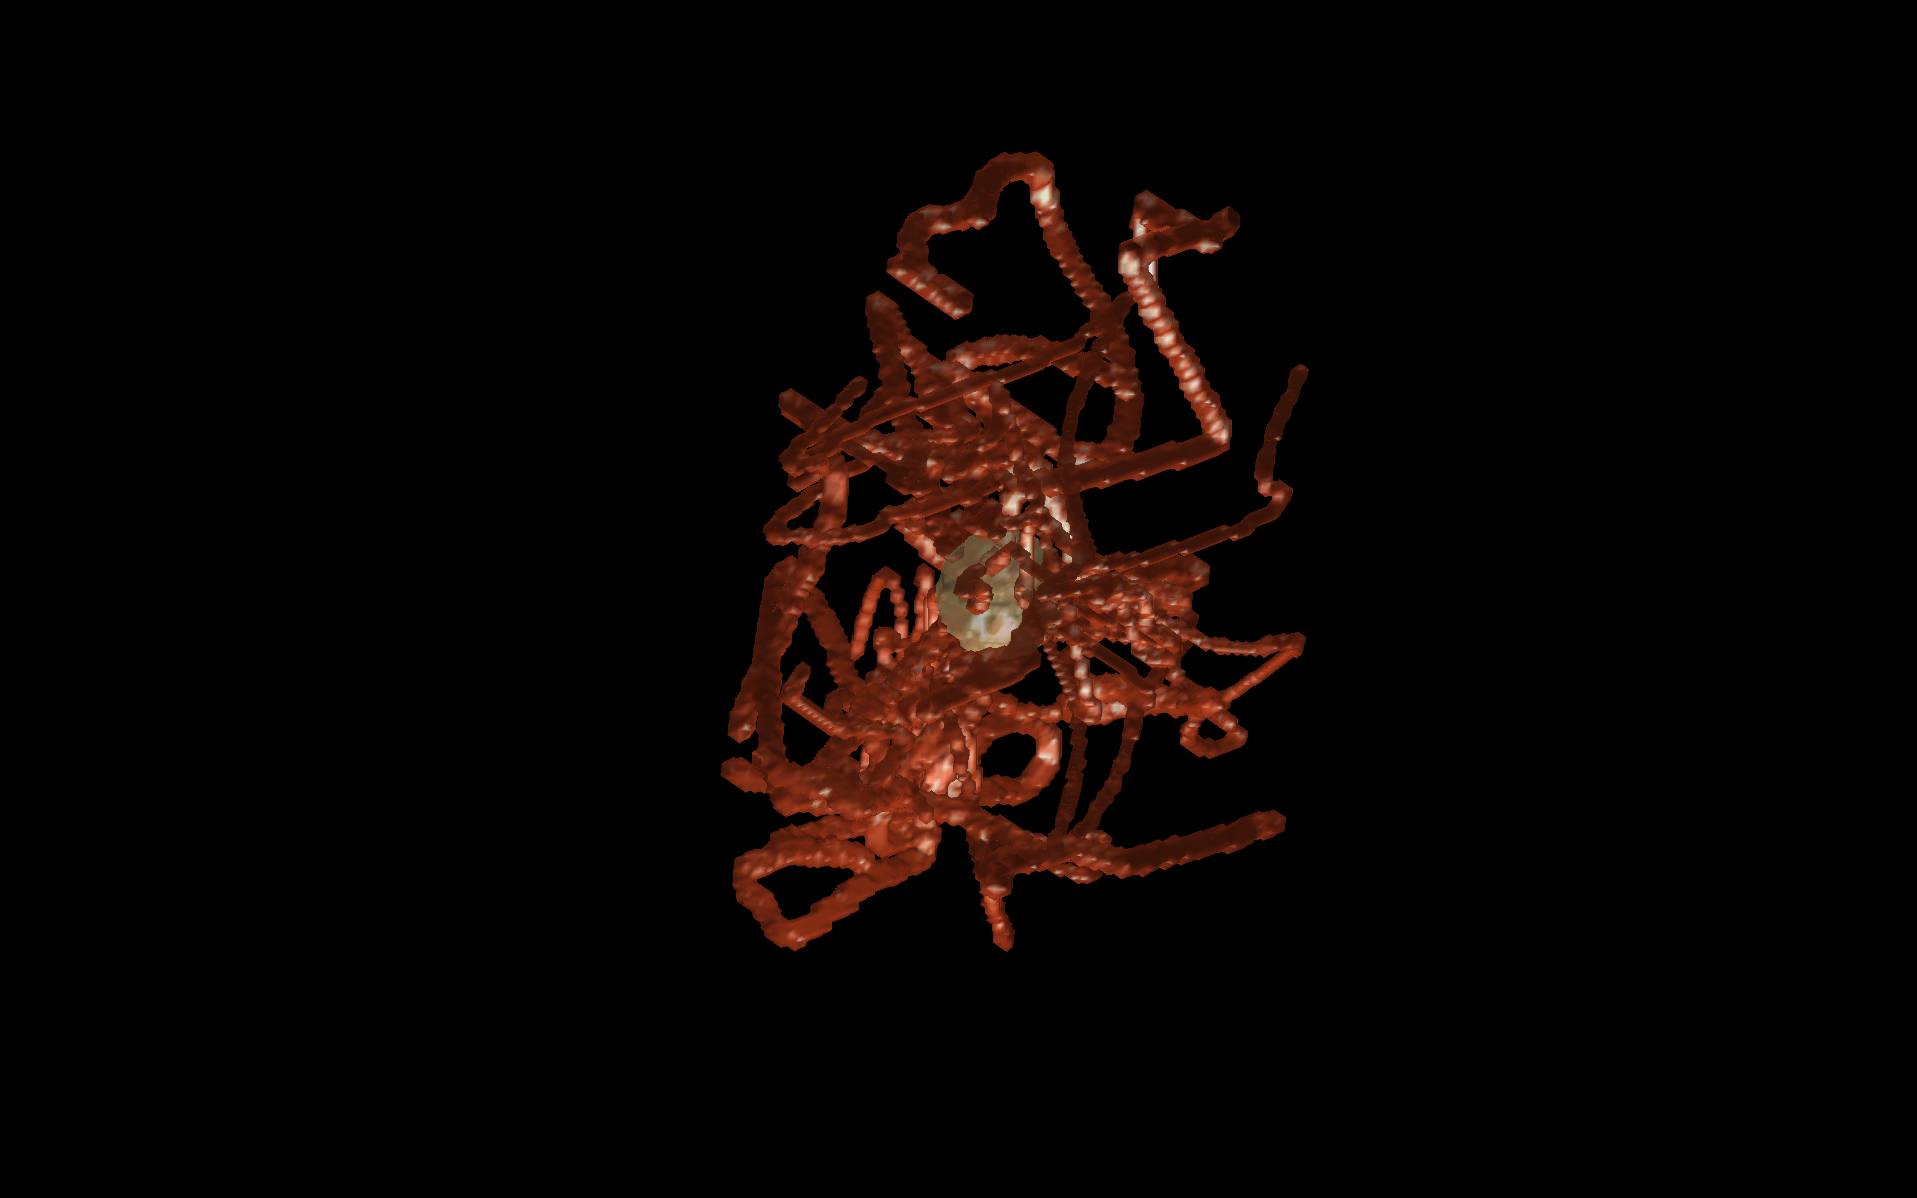

smoothness = 1.5;
rng(2021)
[seg_t2,seg_v2] = create_synthetic_vessel_data(n_tumor_vessels, n_other_vessels, smoothness, numpoints, ... 
        sz, tumor_radius, main_vessel_draw_radius,max_num_branches,...
        branch_probability,branching_radius, vessel_width);
visualize_tumor_and_vessels(seg_v2,seg_t2)

S2 = skeleton(seg_v2|seg_t2);

Distance Map Constructed
Find Branches Iterations : 0
Find Branches Iterations : 1
Find Branches Iterations : 2
The shortest path trace did not finish at the source point
Find Branches Iterations : 3
Find Branches Iterations : 4
Find Branches Iterations : 5
The shortest path trace did not finish at the source point
Find Branches Iterations : 6
Find Branches Iterations : 7
The shortest path trace did not finish at the source point
Find Branches Iterations : 8
Find Branches Iterations : 9
Find Branches Iterations : 10
Find Branches Iterations : 11
Find Branches Iterations : 12
Find Branches Iterations : 13
The shortest path trace did not finish at the source point
Find Branches Iterations : 14
Find Branches Iterations : 15
Find Branches Iterations : 16
Find Branches Iterations : 17
Find Branches Iterations : 18
The shortest path trace did not finish at the source point
Skeleton Branches Found : 34


branch_lengths = [];
for ii = 1:length(S2)
    branch_lengths(ii) = size(S2{ii},1);
end
fprintf('Skeleton contains %d branches, with an average of %0.2f points each',length(S),mean(branch_lengths))

Skeleton contains 39 branches, with an average of 92.47 points each

organization_ftrs2 = compute_quantav_organization(S2, seg_v2, seg_t2, [1,1,1]);
[morphology_ftrs2,branches2] = compute_quantav_morphology(seg_v2,seg_t2,S2);

## Visualizing differences in vessel morphology

Let's compare the expression of QuanTAV features between our two vessel networks visually. We can visualize the curvature along the vessel skeletons and observe that the vessel network created with a lower smoothness setting has more regions of high curvature than the first vessel network. 

curvature


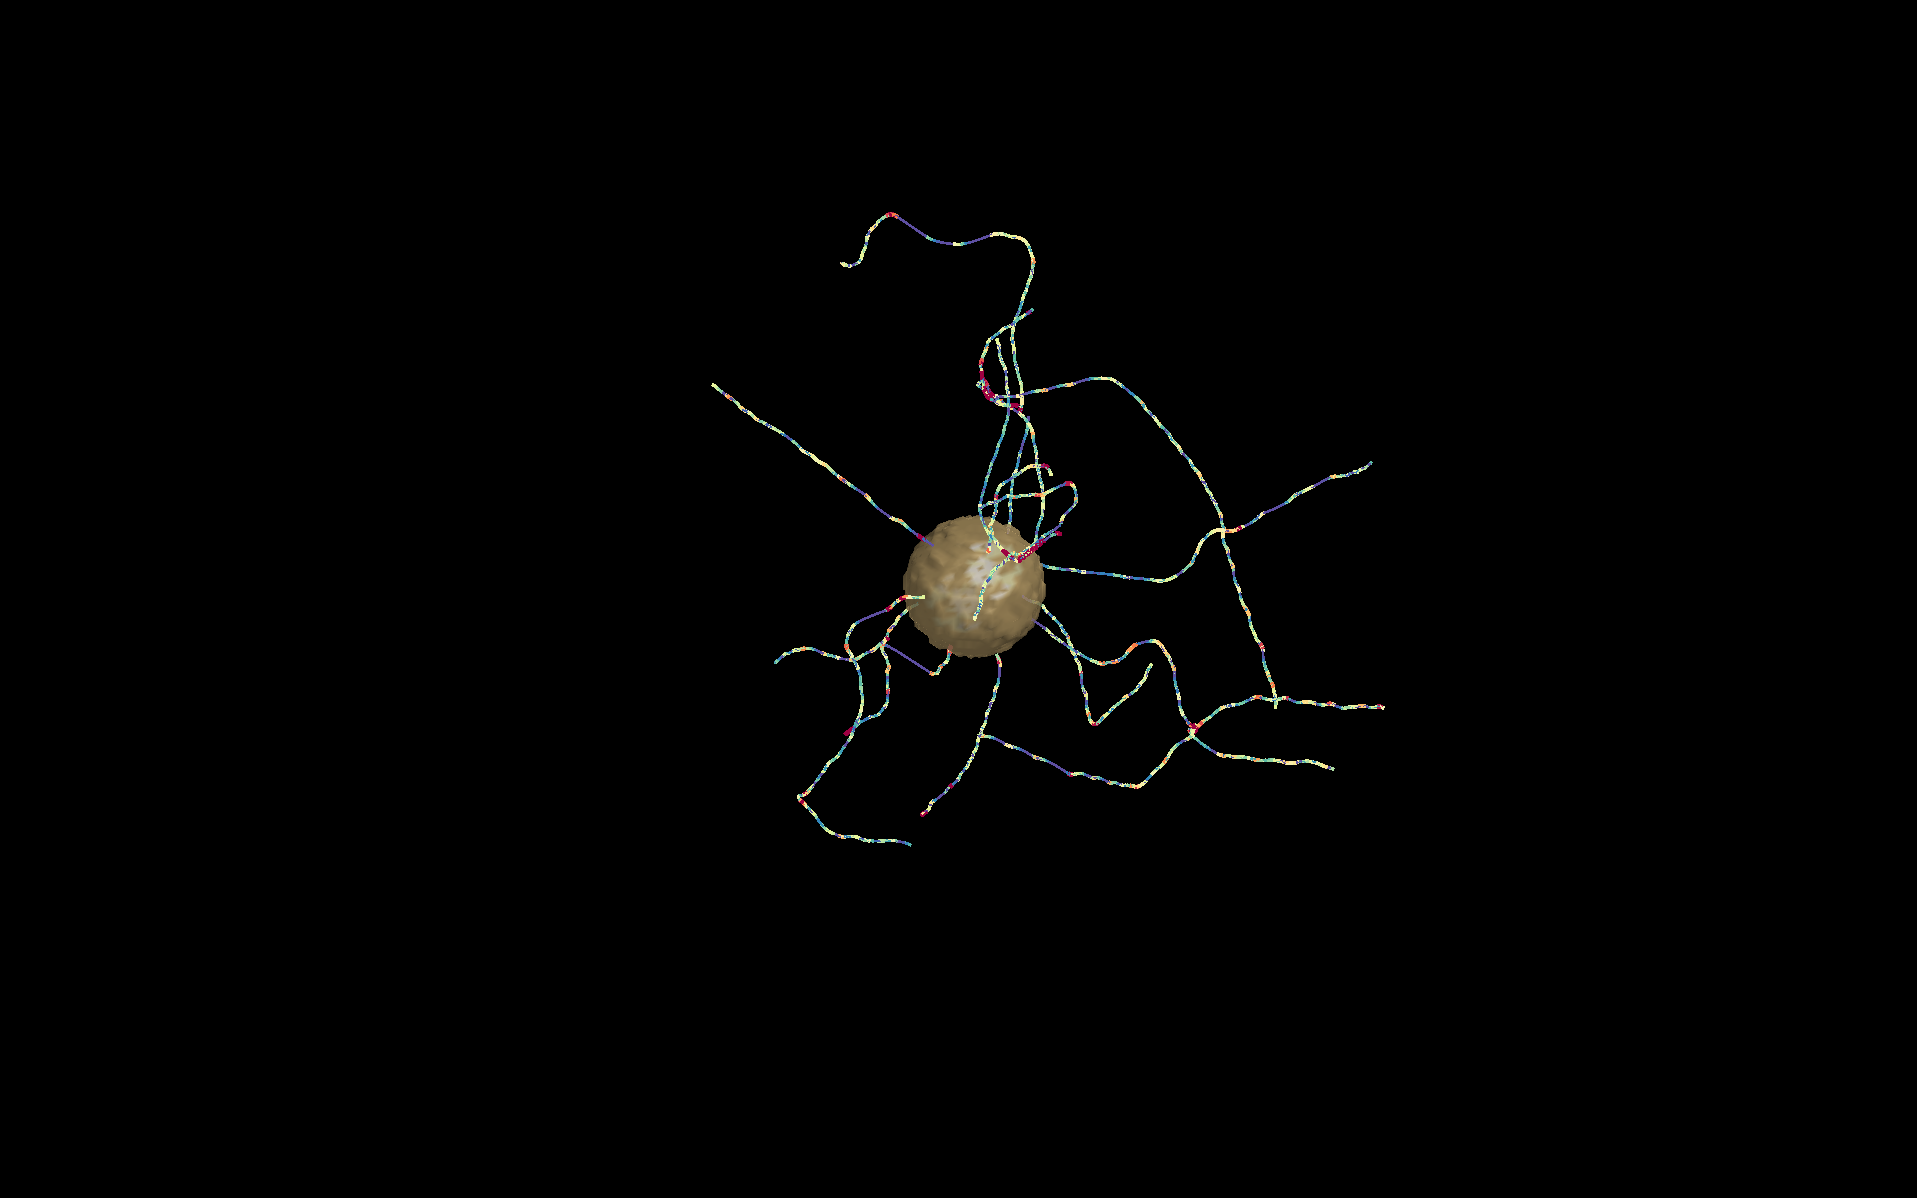

visualize_quantav_morphology(seg_v,seg_t, branches, [.1,.75], 'curvature') % high smoothness 

curvature


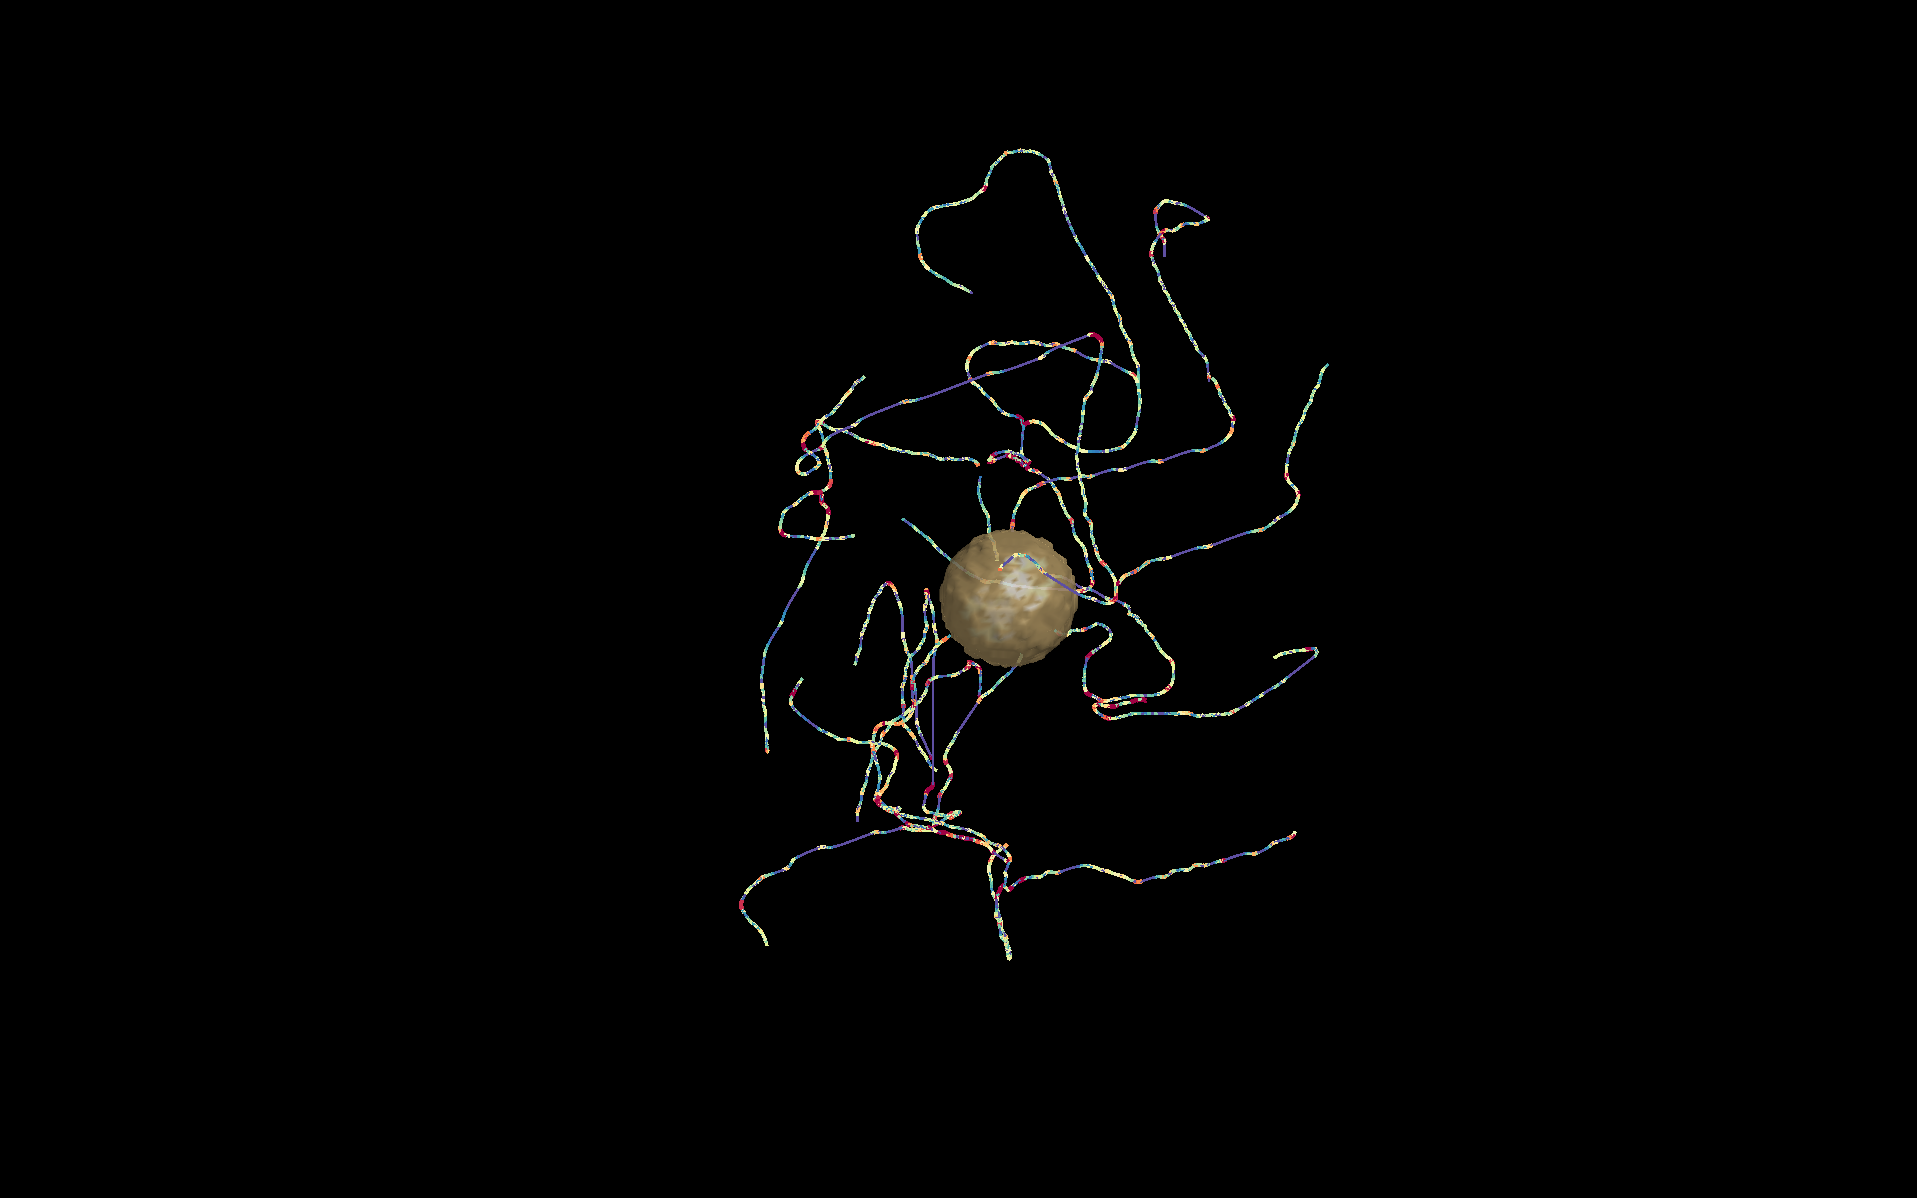

visualize_quantav_morphology(seg_v2,seg_t2, branches2, [.1,.75], 'curvature') % low smoothness 

We can also visualize the increased tortuosity of vessel branches generated with a reduced smoothness setting. 

torsion


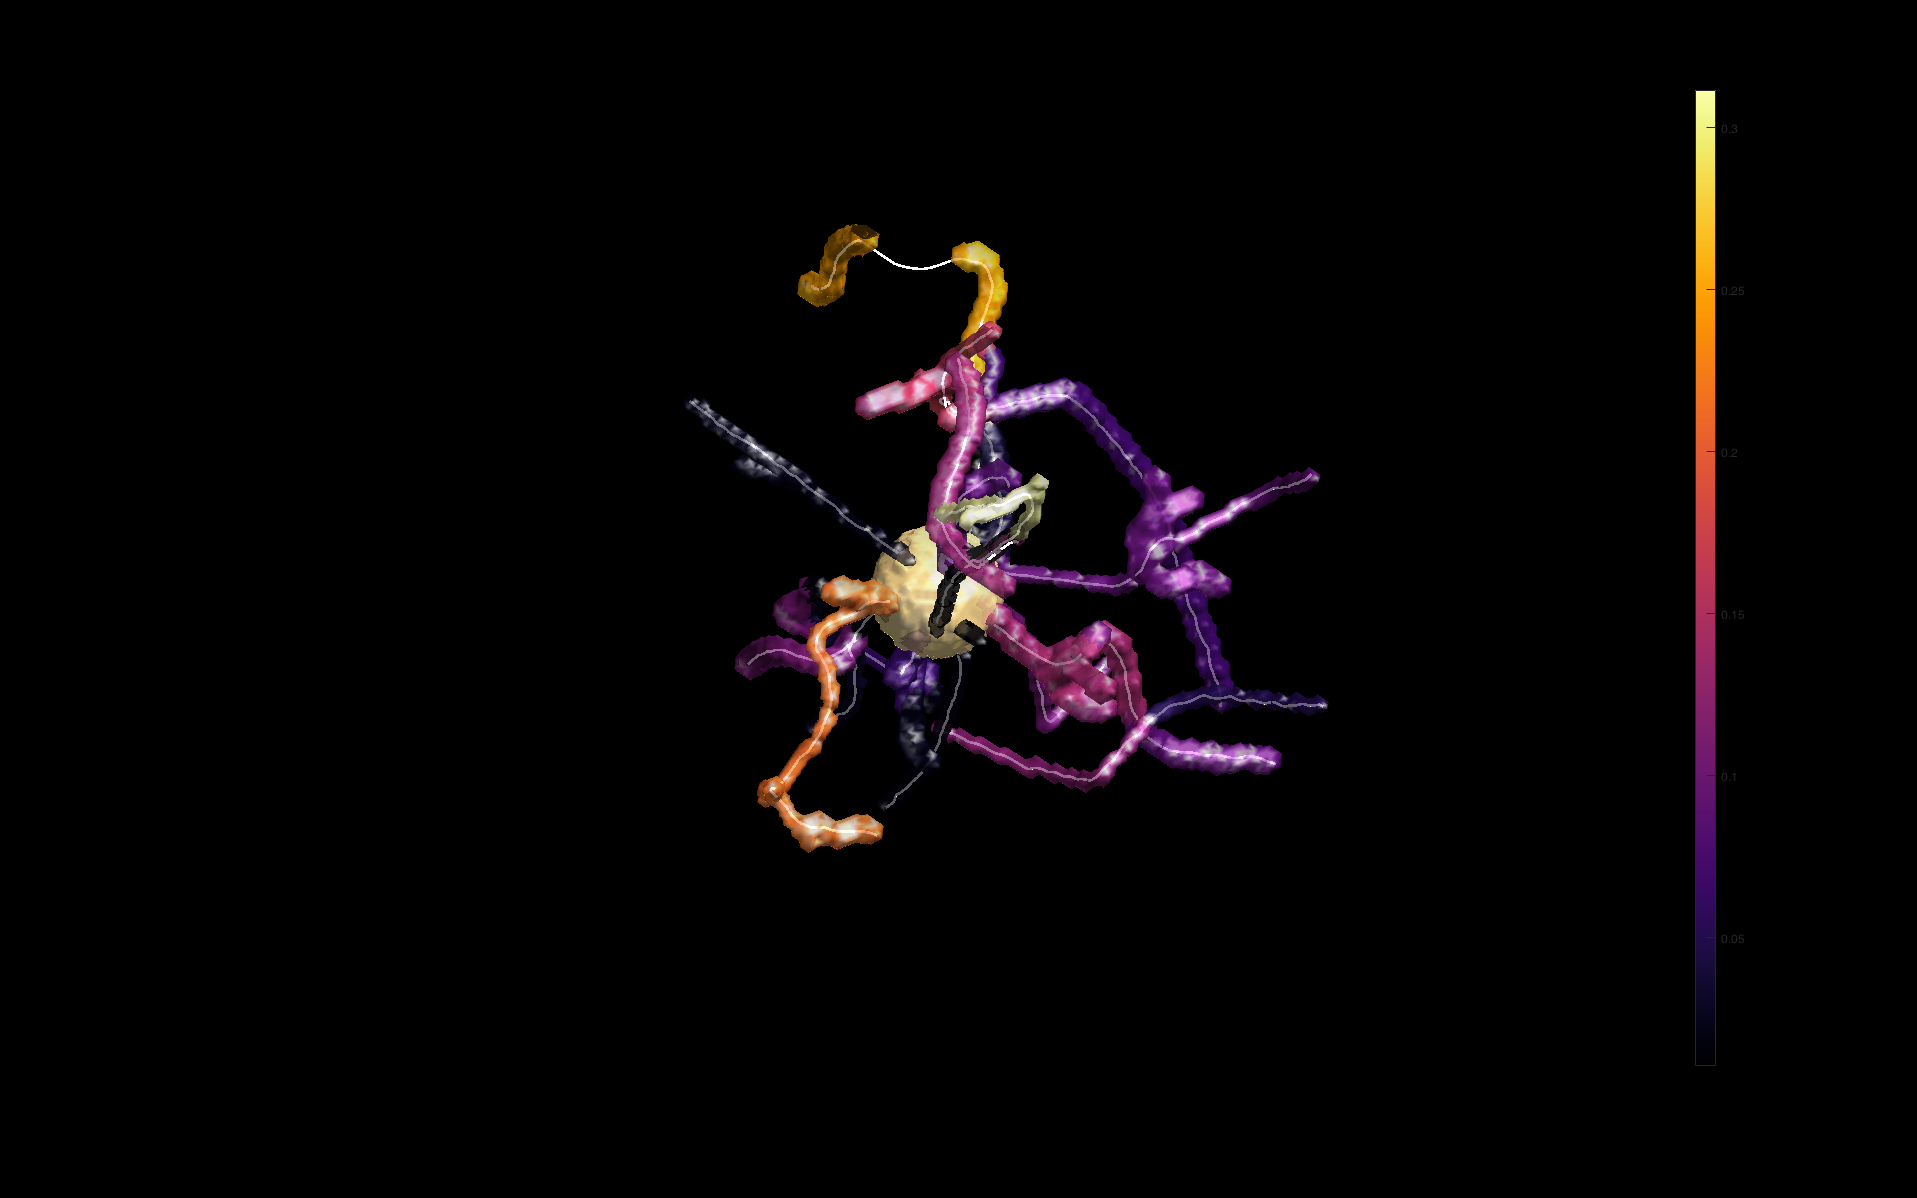

visualize_quantav_morphology(seg_v,seg_t, branches, [.1,.75], 'torsion') % high smoothness 

torsion


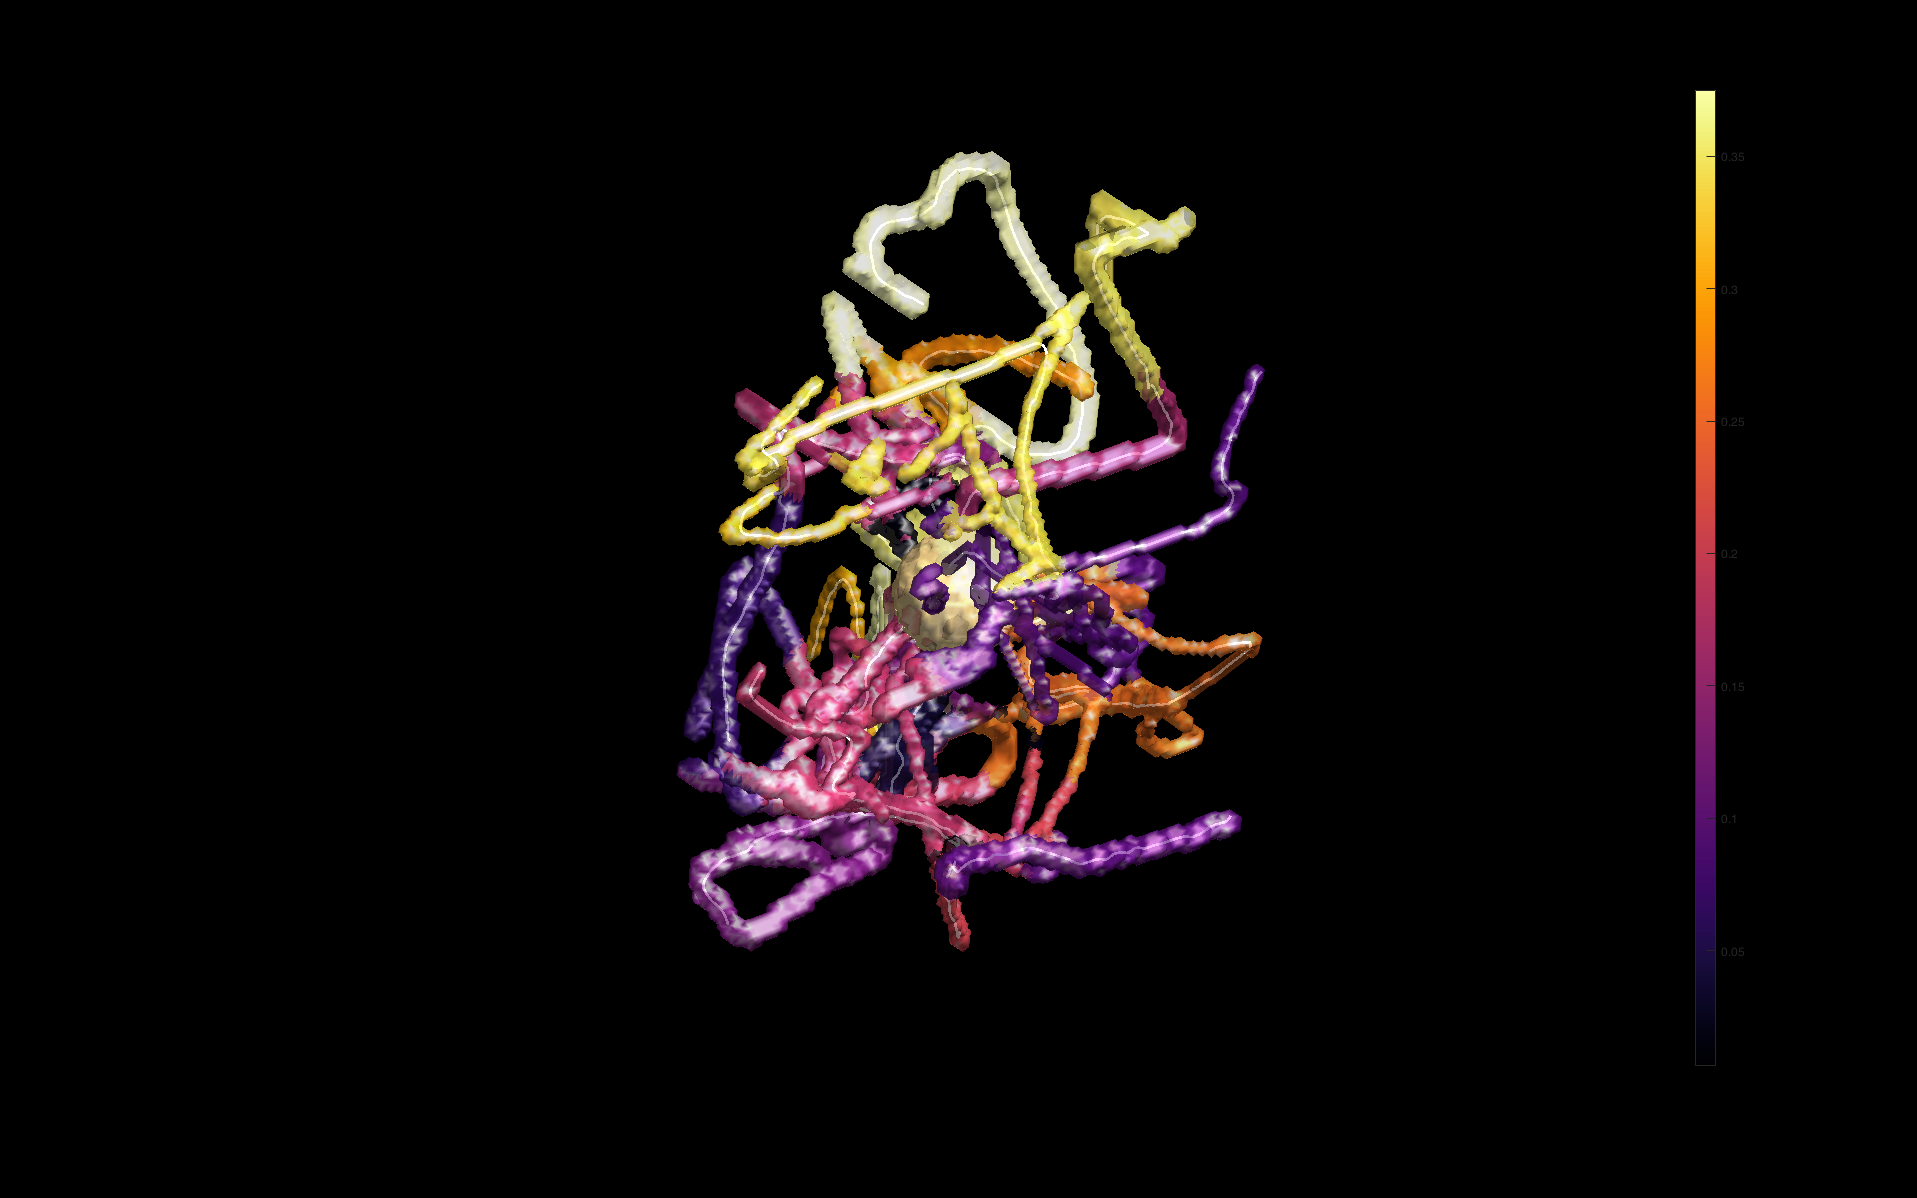

visualize_quantav_morphology(seg_v2,seg_t2, branches2, [.1,.75], 'torsion') % low smoothness 

## QuanTAV measurements distinguish chaotic tumor vasculature 

These differences are also detectable by values of key QuanTAV features. The increased expression of these features indicate a disorganized vessel network and also are associated with poor prognosis and response to treatment involving chemotherapy. The tumor-associated vasculature created with reduced smoothness (Vasculature2) is higher for all example features, as compared to the vessel network generated with a high smoothness setting (Vasculature1). 

feature_vals = {'Feature','Vasculature1','Vasculature2'};
idx = 1; 
feature_vals(end+1,:) = {'QuanTAV Morphology: Mean vessel torsion', morphology_ftrs(idx), morphology_ftrs2(idx)};
idx = 12;
feature_vals(end+1,:) = {'QuanTAV Morphology: Deviation of curvature along vessel branch, standard deviation', morphology_ftrs(idx), morphology_ftrs2(idx)};
idx = 23;
feature_vals(end+1,:) = {'QuanTAV Spatial Organization: Standard deviation of orientation on distance-rotation vessel map', organization_ftrs(idx), organization_ftrs2(idx)};
T = table(feature_vals(2:end,2),feature_vals(2:end,3),'RowNames',feature_vals(2:end,1),'VariableNames',feature_vals(1,2:end));
disp(T)

                                                                                                       Vasculature1    Vasculature2
                                                                                                       ____________    ____________

    QuanTAV Morphology: Mean vessel torsion                                                             [ 0.1970]       [ 0.3703]  
    QuanTAV Morphology: Deviation of curvature along vessel branch, standard deviation                  [ 1.2446]       [ 5.2146]  
    QuanTAV Spatial Organization: Standard deviation of orientation on distance-rotation vessel map     [12.0292]       [41.9706]  

